Funkce

function f_g = konvoluce(f, g)
N = length(f);
M = length(g);
f_g = zeros(N+M-1,1);

for n = 1:(N+M-1)
    sum = 0;
    for m = 1:N
        k = n - m + 1;
        if k >= 1 && k <= M
            sum = sum + f(m) * g(k);
        end
    end
    f_g(n) = sum;
end
end

%
function Y = konvoluce2(img,kernel,mode)
%pro AXI 4 přidat t_valid a t_ready

%Velikosti img a kernelu jako parametry generate
[rows, cols] = size(img);
[K,~] = size(kernel);
shift = floor(K/2);
offset = K-1; % nebo 2*shift

switch mode
    case 'same'
        max_r = rows + 2*shift; %Přes všechny řádky+nulovou hranici
        max_c = cols + 2*shift; %Přes všechny sloupce+nulovou hranici
        Y = zeros(size(img)); % Initialize the output matrix
        borderValue = 0;%může být 0, 127 nebo 255
    case 'valid'
        max_r = rows;
        max_c = cols;
        Y = zeros(size(img)-2*shift); % Initialize the output matrix
    otherwise
        error('Neznámý mód konvoluce.');
end

%jako samostaná entita
LineBuffer=zeros(K,max_c); %Počet Linebufferu odpovídá rozměru kernenu a délce řádku (tedy počtu sloupců)

%taky jako samostatná entita?
WindowBuffer=zeros(K);

for r=1:max_r %Přes všechny řádky
    for c=1:max_c %Přes všechny sloupce
        switch mode
            case 'same'
                if (r <= shift || c <= shift || r>rows+shift || c>cols+shift)
                    %čtení nulového paddingu
                    newPixel=borderValue;
                else
                    %čtení platných pixelů
                    newPixel=img(r-shift,c-shift);
                end
            case 'valid'
                newPixel=img(r,c); %pouze pomocná proměnná
            otherwise
                error('Neznámý mód konvoluce.');
        end

        % 1. Aktualizace LineBufferu (zpoždění po řádcích)
        for k = K:-1:2
            LineBuffer(k, c) = LineBuffer(k-1, c);
        end
        LineBuffer(1, c) = newPixel;

        % 2. Aktualizace WindowBufferu (okno posuvných registrů)
        for k = K:-1:2
            WindowBuffer(:, k) = WindowBuffer(:, k-1);
        end
        % Do prvního sloupce vložíme ten náš aktuální z LineBufferu
        WindowBuffer(:, 1) = LineBuffer(1:K, c);

        acc = 0;
        if c >= K && r >= K
            for i=1:K
                for j = 1:K
                    acc=acc + WindowBuffer(i,j)*kernel(i,j);
                end
            end
            %Y(r-offset,c-offset)=sum(sum(WindowBuffer.*kernel));
            Y(r-offset,c-offset)=acc;
        end
    end
end
end

Main

clc; close; clear;
%% 1. Test 1D konvoluce
disp('Test 1: 1D konvoluce...');

Test 1: 1D konvoluce...


a = [1; 2; 1; 3; 1; 5; 1];
b = [1; 0; -1];

r1 = konvoluce(a, b); % Předpokládám sjednocené pořadí argumentů
r2 = conv(a, b);

% max(abs(...)) je bezpečnější než sum(...), zabrání vyrušení kladné a záporné chyby
assert(max(abs(r1(:) - r2(:))) < 1e-10, 'Chyba: Výsledky 1D konvoluce se neshodují!');

%% 2. Test 2D Konvoluce - Identita ('same' i 'valid')
disp('Test 2: 2D konvoluce (Identita - SAME a VALID)...');

Test 2: 2D konvoluce (Identita - SAME a VALID)...


img_rand = randi([0 255], 10, 10);
kernel_id = [0 0 0; 0 1 0; 0 0 0];

% Test 'same'
Y_same = konvoluce2(img_rand, kernel_id, 'same');
Y_ref_same = conv2(img_rand, kernel_id, 'same');
assert(max(abs(Y_same(:) - Y_ref_same(:))) < 1e-10, 'Chyba: 2D Identita (same) selhala!');

% Test 'valid'
Y_valid = konvoluce2(img_rand, kernel_id, 'valid');
Y_ref_valid = conv2(img_rand, kernel_id, 'valid');
assert(max(abs(Y_valid(:) - Y_ref_valid(:))) < 1e-10, 'Chyba: 2D Identita (valid) selhala!');

%% 3. Test 2D Konvoluce - Detekce hran (Sobelův filtr)
disp('Test 3: 2D konvoluce (Sobel / sektory)...');

Test 3: 2D konvoluce (Sobel / sektory)...


kernel_sobel = [-1, 0, 1;
                -2, 0, 2;
                -1, 0, 1];

% Vytvoření testovacího obrázku pomocí vektorizace (čistší a rychlejší než for cykly)
img_sec = zeros(10, 10);
img_sec(1:5, 1:5) = 0;
img_sec(6:10, 1:5) = 127;
img_sec(1:5, 6:10) = 63;
img_sec(6:10, 6:10) = 255;

Y_sobel = konvoluce2(img_sec, kernel_sobel, 'valid');
Y_ref_sobel = conv2(img_sec, kernel_sobel, 'valid');
assert(max(abs(Y_sobel(:) - Y_ref_sobel(:))) < 1e-10, 'Chyba: Sobel filtr selhal!');

%% 4. Test 2D Konvoluce - Průměrovací filtr (Box blur)
disp('Test 4: 2D konvoluce (Průměrovací filtr / Box blur)...');

Test 4: 2D konvoluce (Průměrovací filtr / Box blur)...


kernel_box = (1/9) * ones(3);

Y_box = konvoluce2(img_rand, kernel_box, 'same');
Y_ref_box = conv2(img_rand, kernel_box, 'same');
assert(max(abs(Y_box(:) - Y_ref_box(:))) < 1e-10, 'Chyba: Průměrovací filtr selhal!');

%% 5. Test 2D Konvoluce - Gaussův filtr (Gaussovo rozostření)
disp('Test 5: 2D konvoluce (Gaussův filtr)...');

Test 5: 2D konvoluce (Gaussův filtr)...


% Důležité: Filtr se musí vydělit součtem svých prvků (16), jinak by nešlo o průměrování
kernel_gauss = [1 2 1; 2 4 2; 1 2 1] / 16; 

Y_gauss = konvoluce2(img_rand, kernel_gauss, 'valid');
Y_ref_gauss = conv2(img_rand, kernel_gauss, 'valid');
assert(max(abs(Y_gauss(:) - Y_ref_gauss(:))) < 1e-10, 'Chyba: Gaussův filtr selhal!');

disp('VŠECHNY TESTY PROŠLY ÚSPĚŠNĚ!');

VŠECHNY TESTY PROŠLY ÚSPĚŠNĚ!


Převody barevných soustav

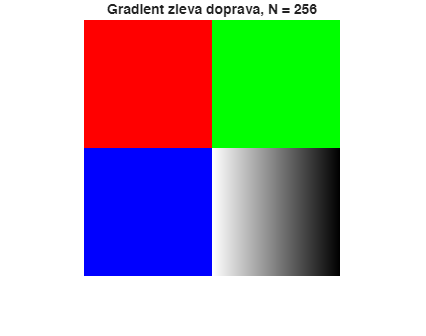

% 1. Definice rozlišení
N = 256; 
mid = round(N/2); 

% 2. Inicializace obrázku
img = zeros(N, N, 3, 'uint8');

% 3. Výplň kvadrantů
img(1:mid, 1:mid, 1) = 255;      % Červená (levý horní)
img(1:mid, mid+1:N, 2) = 255;    % Zelená (pravý horní)
img(mid+1:N, 1:mid, 3) = 255;    % Modrá (levý dolní)

% 4. Pravý dolní čtverec: Gradient (Bílá -> Černá, ZLEVA DOPRAVA)
steps = N - mid; 
grad_values = linspace(255, 0, steps);

% Změna: Teď rozkopírujeme řádkový vektor 50x pod sebe
% (nebo vezmeme sloupcový a transponujeme ho)
gradient_block = repmat(grad_values, steps, 1);

% Vložení do všech kanálů
img(mid+1:N, mid+1:N, 1) = uint8(gradient_block);
img(mid+1:N, mid+1:N, 2) = uint8(gradient_block);
img(mid+1:N, mid+1:N, 3) = uint8(gradient_block);

% 5. Zobrazení a uložení
imshow(img);
title(['Gradient zleva doprava, N = ', num2str(N)]);


filename = sprintf('testovaci_obraz_horiz_%dx%d.bmp', N, N);
imwrite(img, filename);

% Uložení s dynamickým názvem
filename = sprintf('testovaci_obraz_%dx%d.bmp', N, N);
imwrite(img, filename);

% 6. Uložení jako bitmapu (.bmp)
imwrite(img, 'testovaci_obrazek.bmp');